# **2 - INTEREST RATES BOOTSTRAP**

## **EXERCISE 1: **Bootstrap for Euribor 3M Interbank curve

Considering the inter-bank market on the 15th of February 2008 at 10:45 C.E.T. Implement the code necessary to realize the bootstrap for the Discount Factors' curve (with a single-curve model). Output values should be on settlement date and expires of quoted underlings. Hints: include in the datesSet of the bootstrap only end dates of underlying contracts.

### **SETUP**

% Initialize workspace
clc; clear; close all;

% Fix randomness
rng('default');   

% Add shared library folder
addpath(genpath(fullfile('..','..','lib')));

% Add project-specific folders
addpath(genpath('src'));
addpath(genpath('data'));
addpath(genpath('results'));

% Define paths
resultsPath = fullfile('results');
figuresPath = fullfile('results', 'figures');
srcPath = fullfile('src');
dataRawPath = fullfile('data', 'raw');
dataInterimPath = fullfile('data', 'interim');
dataProcessedPath = fullfile('data', 'processed');
libPath = fullfile('..','..','lib');

### **UPLOAD DATA**

filename = fullfile(dataRawPath, 'MktData_CurveBootstrap');
dateFormat = 'dd/MM/yyyy';
[datesSet, ratesSet] = ReadExcelData(filename, dateFormat);

### **BOOTSTRAP DISCOUNT AND ZERO RATES**

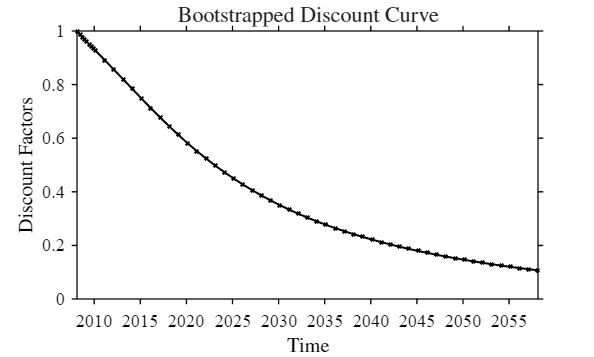

[dates, discounts] = Bootstrap(datesSet, ratesSet);
zRates = zeroRatesShift(dates, discounts);

figDISC = figure;
plot(dates, discounts, '-x', 'DisplayName', 'Bootstrapped Discount'); hold on;
PlotUtils.setStyle();
PlotUtils.setLabels('Time', 'Discount Factors', ...
    'Bootstrapped Discount Curve');

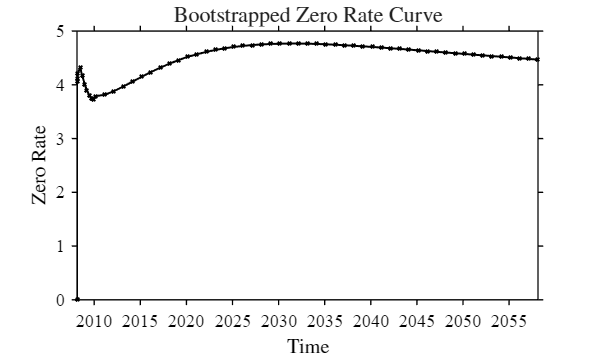

figRATES = figure;
plot(dates, 100 * zRates, '-x', 'DisplayName', 'Bootstrapped Zero Rates');
PlotUtils.setStyle();
PlotUtils.setLabels('Time', 'Zero Rate', ...
    'Bootstrapped Zero Rate Curve');

## **EXERCISE 2: Sensitivities for an IRS**

With the discount curve obtained above compute the absolute value of the quantities specified below for a portfolio composed only by one single swap. A 6y plain vanilla IR swap vs Eurbibor 3m with a fixed rate 2.817% and a Notional of €10 Mln:

- DV01-parallel shift;

- DV01(z)-parallel shift;

- BPV of the 5y IRS;

For "I.B. coupon bond" with same expiry, fixed rate & reset dates of the IRS, and face value equal to IRS Notional:

- its Macaulay Duration.

### **SETUP**

% Initialize workspace
clc; clear; close all;

% Fix randomness
rng('default');   

% Add shared library folder
addpath(genpath(fullfile('..','..','lib')));

% Add project-specific folders
addpath(genpath('src'));
addpath(genpath('data'));
addpath(genpath('results'));

% Define paths
resultsPath = fullfile('results');
figuresPath = fullfile('results', 'figures');
srcPath = fullfile('src');
dataRawPath = fullfile('data', 'raw');
dataInterimPath = fullfile('data', 'interim');
dataProcessedPath = fullfile('data', 'processed');
libPath = fullfile('..','..','lib');

### **UPLOAD DATA**

BootstrapCurves = load(fullfile(libPath, 'BootstrapCurves.mat'));
dates = BootstrapCurves.dates;
discounts = BootstrapCurves.discounts;
zeroRatesShift = ZeroRates(dates, discounts) + 1e-4;
discounts_DV01 = Discounts(dates, zeroRatesShift);

SwapData = load(fullfile(dataRawPath, 'SwapData.mat'));
setDate = SwapData.SettlementDate;
fixedLegPaymentDates = SwapData.FixedLegDates;
fixedRate = SwapData.FixedRate;

### **COMPUTE SENSITIVITIES**

[DV01, BPV, DV01_z] = SensSwap(setDate, fixedLegPaymentDates, fixedRate, dates, discounts, discounts_DV01);
T = table(DV01 * 1e4, DV01_z * 1e4, BPV * 1e4, 'VariableNames', {'DV01', 'DV01 Zero Rates', 'BPV'})

T = 1×3 table
     DV01     DV01 Zero Rates     BPV  
    ______    _______________    ______

    5.2049        5.2049         5.2399
